**Multiobjective Optimization. Nonlinear problem. Scalarization Method.**


$$\left\lbrace \begin{array}{ll}
\mathrm{minimize} & \left(x_1 \right),\left(x_1^2 +x_2^2 -2x_1 \right)\\
\mathrm{subject}\;\mathrm{to} & -x_1 \le 0\\
\; & -x_2 \le 0\\
\; & x_1 +x_2 \le 2
\end{array}\right.$$


a) Find the set of weak minima by means of the scalarization method. 

b) What is the set of minima?

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

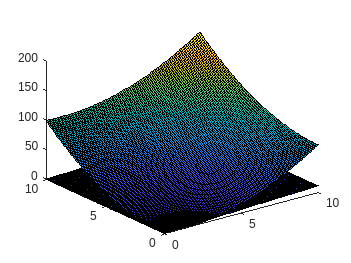

x1 = 0:0.1:10;
x2 = 0:0.1:10;

[X1, X2] = meshgrid(x1,x2);

X3 = X1;
X4 = X1.^2 + X2.^2 -2.*X1;

surface(X1,X2,X3);
hold on
surface(X1,X2,X4);
view(3);
hold off

% 2D
x4 = sqrt(-x1.^2 + 2.*x1);
x3 = x1;

plot(x1,x4);

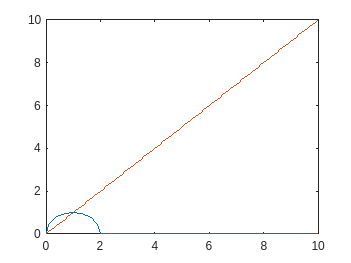

hold on
plot(x1,x3);
hold off

condition_x1 = X1((-X1<=0) & (-X2<=0) & (X1+X2<=2)); 
condition_x2 = X2((-X1<=0) & (-X2<=0) & (X1+X2<=2));

plot(condition_x1, condition_x2, 'b.');

hold on

Q = [2 0
     0 2];

c = [-2
      0];

A = [ -1  0
       0 -1
       1  1];

b = [0
     0
     2];

options = optimset('Display', 'off');

for alpha = 0.001:0.001:0.999
    Q_alpha = Q*alpha;
    c_alpha = [1-3*alpha ; 0];
    x = quadprog(Q_alpha, c_alpha, A,b,[],[],[],[],[],options);
    plot(x(1), x(2), 'r.');
end

% Alpha 0
alpha = 0;
Q_alpha = Q*alpha;
c_alpha = [1-3*alpha ; 0];
x = quadprog(Q_alpha, c_alpha, A,b,[],[],[],[],[],options);

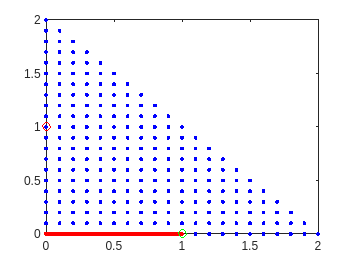

plot(x(1), x(2), 'ro');

% Alpha 1
alpha = 1;
Q_alpha = Q*alpha;
c_alpha = [1-3*alpha ; 0];
x = quadprog(Q_alpha, c_alpha, A,b,[],[],[],[],[],options);
plot(x(1), x(2), 'go');

hold off